变步长梯度下降法，是在固定步长梯度下降法的基础上，将每一步梯度下降过程的步长都通过计算冲新区确定，从而兼顾准确性和收敛性，减少算法的运行时间

next = now - learning_rate*▽f

clear;
clc;
%确定目标函数
func = @(x,y) x.^3 + y.^2 - x.*y + 5.*y + 3.*x + 15*sin(x*y) + 10*cos(3*x)

func = 包含以下值的 function_handle :
    @(x,y)x.^3+y.^2-x.*y+5.*y+3.*x+15*sin(x*y)+10*cos(3*x)


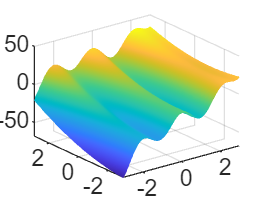

%设置求解区间
x_str=-3;
x_end=3;
y_str=-3;
y_end=3;
forward_step=0.01;
x=x_str:forward_step:x_end;
y=y_str:forward_step:y_end;
[xx,yy]=meshgrid(x,y);
z=func(xx,yy);
mesh(xx,yy,z);

求解梯度的函数

point = [2 2];
grad = CalGard(z,xx,yy,point);

计算步长的函数

lr = 0.3;%不会写变步长，下面是梯度下降算法
point = point - grad*lr;
